## Monte Carlo Final Project

**Constants**

clc
clear
close all

q = 1.602e-19; % C
E = [0.5 1 2 5 8 10] * 1e5;
h = 6.626e-34; % Joule seconds
h_bar = h / (2*pi); % Joule seconds
KB_J = 1.381e-23; % Boltzmann constant in J/K
T = 300; % room temperature at degrees K
N = 1000; % number of particles
m_e = 9.109e-31; % electron rest mass in kg
m_gamma = 0.067 * m_e; % effective mass of electron in gamma valley
m_X = 0.58 * m_e; % effective mass of electron in X valley
m_L = 0.17 * m_e; % effective mass of electron in L valley
m_eff = [m_gamma m_X m_L];
E_phonon = 35.36e-3 * q; % energy of a phonon in GaAs in J
w_LO = E_phonon / h_bar; % rad/s for phonon in GaAs
e_s = 12.9; % static dielectric constant
e_inf = 10.92; % high-frequency dielectric constant
e_0 = 8.854e-12; % vacuum permittivity in F/m
t_max = 30e-12; % length of simulation (30 picoseconds)
t_ensemble = 5e-15; % length of ensemble (5 femtoseconds)
ensemble_count = round(t_max / t_ensemble); % amount of ensembles
E_count = 1;
dt = 1e-16; % length of unit of time (.1 femtoseconds)
N_0 = 1 / (exp(E_phonon / (KB_J * T)) - 1); % phonon occupation number
p = 5370; % mass density of GaAs, kg/m^3
time_count = round(t_max / dt);
Z_if = [0 3 4
        1 2 4
        1 3 3]; % # of final valleys
D_if = [0 10 1.8
        10 10 1
        1.8 1 5] * (q / 1e-10); % from eV / Angstrom to J/m
E_if = [0 .48 .29
       -.48 0 -.19
       -.29 .19 0] * q;
inter_phonon = [0 .0299 .0278
              .0299 .0299 .0293
              .0278 .0293 .029] * q; % intervalley phonon energy in eV
w_if = inter_phonon / h_bar;
D_acoustic = [7.01 9 9.2] * q; % Deformation potential in J for gamma, X, L valley
v_s = 5220; % sound velocity in GaAs in m/s
scatter_0 = 1.2e14; % this was determined from calculating the scattering rates
                    % in a different .mlx file
v_z_ensemble = zeros(ensemble_count, length(E));
E_ensemble = v_z_ensemble;
k_x_ensemble = v_z_ensemble;
k_y_ensemble = v_z_ensemble;
k_z_ensemble = v_z_ensemble;
v_x_ensemble = zeros(ensemble_count, 1);
v_y_ensemble = zeros(ensemble_count, 1);
valley_ensemble = zeros(ensemble_count, length(E) * 3); % length(E) * 3 for the three valleys per E-field simulation
E_ensemble_gamma = zeros(ensemble_count, length(E));
E_ensemble_X = zeros(ensemble_count, length(E));
E_ensemble_L = zeros(ensemble_count, length(E));

**Self-Scattering Properties**

When self-scattering occurs, only a new free flight time is generated and no scattering happens. These are the properties that must be true.

elastic = 1; % if high (1), then ellastic, if low (0), inelastic
isotropic = 1; % if high (1), then isotropic, if low (0), anisotropic
inter = 0; % if high (1), then intervalley scattering, if low (0), same valley
absorb = 0; % if high (1), then absorbing, if low (0), emitting or neither
emit = 0; % if high (1), then emitting, if low (0), absorbing or neither

**Initial Values**

rng(671); % the random number seed I spammed on my keyboard

**Scattering Begins!**

for c = 1:length(E)
    i_ensemble = 1;
    E_kin = (-1.5) * KB_J * T * log(rand(N, 1));
    phi = 2 * pi * rand(N, 1);
    theta = acos(1 - 2 * rand(N, 1));
    k = sqrt((2 * m_gamma * E_kin) / (h_bar ^ 2));
    k_x = k .* sin(theta) .* cos(phi);
    k_y = k .* sin(theta) .* sin(phi);
    k_z = k .* cos(theta);
    v_z = k_z * h_bar / m_gamma;
    v_y = k_y * h_bar / m_gamma;
    v_x = k_x * h_bar / m_gamma;
    valley_index = ones(N, 1); % gamma is 1, X is 2, L is 3
    E_ensemble(i_ensemble, E_count) = mean(E_kin);
    k_x_ensemble(i_ensemble, E_count) = mean(k_x);
    k_y_ensemble(i_ensemble, E_count) = mean(k_y);
    k_z_ensemble(i_ensemble, E_count) = mean(k_z);
    edges = 0.5:1:3.5;                % Bins centered on 1, 2, 3
    counts = histcounts(valley_index, edges);   % Count occurrences
    col_idx = (E_count - 1) * 3 + (1:3); % Compute the correct column indices
    valley_ensemble(i_ensemble, col_idx) = counts / sum(counts);
    v_x_ensemble(1, 1) = mean(v_x);
    v_y_ensemble(1, 1) = mean(v_y);
    v_z_ensemble(1, E_count) = mean(v_z);
    t_ff = -log(1 - rand(N, 1)) / (scatter_0);
    is_gamma = valley_index == 1;
    is_X = valley_index == 2;
    is_L = valley_index == 3;
    
    E_ensemble_gamma(i_ensemble, E_count) = mean(E_kin(is_gamma));
    E_ensemble_X(i_ensemble, E_count) = mean(E_kin(is_X));
    E_ensemble_L(i_ensemble, E_count) = mean(E_kin(is_L));

**1) Histogram of initial energy distribution and initial momentum along the z-axis**

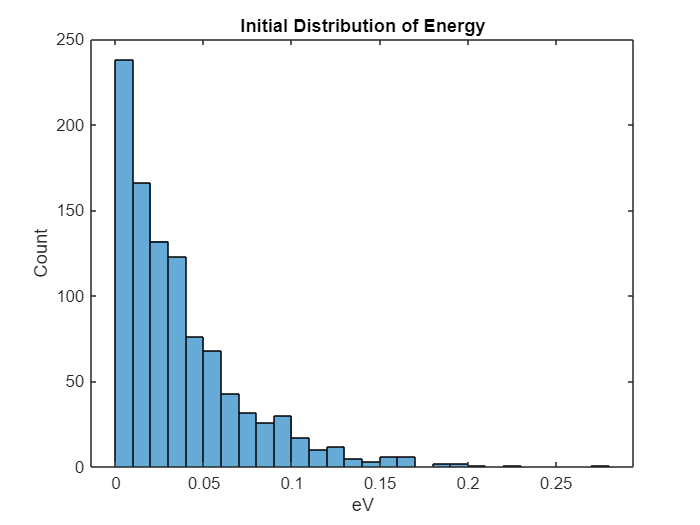

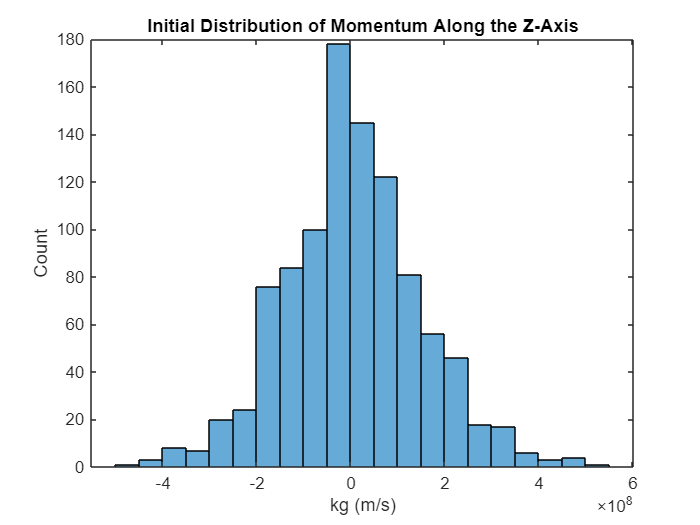

    if (c == 1)
        figure;
        histogram(E_kin / q);
        title('Initial Distribution of Energy');
        xlabel('eV');
        ylabel('Count');

        figure;
        histogram(k_z);
        title('Initial Distribution of Momentum Along the Z-Axis');
        xlabel('kg (m/s)');
        ylabel('Count');
    end

    for t = dt:dt:t_max 
        % at each unit of time throughout the duration of the simulation
    
        for i = 1:N
            % for each particle
               
            if t_ff(i) > 0
                k_z_new = k_z(i) - (dt * q * E(c)) / h_bar;
                k_z(i) = k_z_new;
                v_z(i) = k_z_new * h_bar / (m_eff(valley_index(i)));
                t_ff(i) = t_ff(i) - dt;
                E_kin(i) = (h_bar ^ 2 / 2) * (k_x(i) ^ 2 + k_y(i) ^ 2 + k_z(i) ^ 2) ...
                    / m_eff(valley_index(i));
            else
                % scattering is finished, a new flight-time is needed
    
                % less than or equal to because our random flight times
                % won't perfectly line up with each dt

                index = valley_index(i);
                m = m_eff(index);
                D = D_acoustic(index);

                if index == 1 % initial valley (gamma valley)
                    scatter_1 = ac_scatter(E_kin(i), m, h_bar, p, v_s, D, KB_J, T);
                    scatter_2 = pop_abs(E_kin(i), m, h_bar, w_LO, E_phonon, KB_J, q, e_inf, e_s, e_0, T) + scatter_1;
                    scatter_3 = pop_emit(E_kin(i), m, h_bar, w_LO, E_phonon, KB_J, q, e_inf, e_s, e_0, T) + scatter_2;
                    f = 2; % final valley (X valley)
                    scatter_4 = inter_scatter_abs(E_kin(i), h_bar, KB_J, T, D_if(index, f), Z_if(index, f), w_if(index, f), E_if(index, f), m_eff(f), p, inter_phonon(index, f)) + scatter_3;
                    scatter_5 = inter_scatter_emit(E_kin(i), h_bar, KB_J, T, D_if(index, f), Z_if(index, f), w_if(index, f), E_if(index, f), m_eff(f), p, inter_phonon(index, f)) + scatter_4;
                    f = 3; % final valley (L valley)
                    scatter_6 = inter_scatter_abs(E_kin(i), h_bar, KB_J, T, D_if(index, f), Z_if(index, f), w_if(index, f), E_if(index, f), m_eff(f), p, inter_phonon(index, f))  + scatter_5;
                    scatter_7  = inter_scatter_emit(E_kin(i), h_bar, KB_J, T, D_if(index, f), Z_if(index, f), w_if(index, f), E_if(index, f), m_eff(f), p, inter_phonon(index, f)) + scatter_6;
                    P = [scatter_1, scatter_2, scatter_3, scatter_4, scatter_5, scatter_6, scatter_7, scatter_0] / scatter_0;
                    r5 = rand() * P(8);
    
                    if r5 < P(1)
                        scattering = 'acoustic';
                        elastic = 1;
                        isotropic = 1;
                        inter = 0;
                        absorb = 0;
                        emit = 0;
                    elseif r5 < P(2)
                        scattering = 'pop_abs';
                        elastic = 0;
                        isotropic = 0;
                        inter = 0;
                        absorb = 1;
                        emit = 0;
                    elseif r5 < P(3)
                        scattering = 'pop_emit';
                        elastic = 0;
                        isotropic = 0;
                        inter = 0;
                        absorb = 0;
                        emit = 1;
                    elseif r5 < P(4)
                        scattering = 'inter_X_abs';
                        elastic = 0;
                        isotropic = 1;
                        inter = 1;
                        absorb = 1;
                        emit = 0;
                        m_f = 2;
                    elseif r5 < P(5)
                        scattering = 'inter_X_emit';
                        elastic = 0;
                        isotropic = 1;
                        inter = 1;
                        absorb = 0;
                        emit = 1;
                        m_f = 2;
                    elseif r5 < P(6)
                        scattering = 'inter_L_abs';
                        elastic = 0;
                        isotropic = 1;
                        inter = 1;
                        absorb = 1;
                        emit = 0;
                        m_f = 3;
                    elseif r5 < P(7)
                        scattering = 'inter_L_emit';
                        elastic = 0;
                        isotropic = 1;
                        inter = 1;
                        absorb = 0;
                        emit = 1;
                        m_f = 3;
                    else
                        scattering = 'self_scatter';
                        elastic = 1;
                        isotropic = 1;
                        inter = 0;
                        absorb = 0;
                        emit = 0;
                    end

                elseif index == 2 % initial valley (X valley)
                    scatter_1 = ac_scatter(E_kin(i), m, h_bar, p, v_s, D, KB_J, T);
                    scatter_2 = pop_abs(E_kin(i), m, h_bar, w_LO, E_phonon, KB_J, q, e_inf, e_s, e_0, T) + scatter_1;
                    scatter_3 = pop_emit(E_kin(i), m, h_bar, w_LO, E_phonon, KB_J, q, e_inf, e_s, e_0, T) + scatter_2;
                    f = 1; % final valley (gamma valley)
                    scatter_4 = inter_scatter_abs(E_kin(i), h_bar, KB_J, T, D_if(index, f), Z_if(index, f), w_if(index, f), E_if(index, f), m_eff(f), p, inter_phonon(index, f)) + scatter_3;
                    scatter_5 = inter_scatter_emit(E_kin(i), h_bar, KB_J, T, D_if(index, f), Z_if(index, f), w_if(index, f), E_if(index, f), m_eff(f), p, inter_phonon(index, f)) + scatter_4;
                    f = 3; % final valley (L valley)
                    scatter_6 = inter_scatter_abs(E_kin(i), h_bar, KB_J, T, D_if(index, f), Z_if(index, f), w_if(index, f), E_if(index, f), m_eff(f), p, inter_phonon(index, f))  + scatter_5;
                    scatter_7  = inter_scatter_emit(E_kin(i), h_bar, KB_J, T, D_if(index, f), Z_if(index, f), w_if(index, f), E_if(index, f), m_eff(f), p, inter_phonon(index, f)) + scatter_6;
                    f = 2; % final valley (X valley, again)
                    scatter_8 = inter_scatter_abs(E_kin(i), h_bar, KB_J, T, D_if(index, f), Z_if(index, f), w_if(index, f), E_if(index, f), m_eff(f), p, inter_phonon(index, f))  + scatter_7;
                    scatter_9  = inter_scatter_emit(E_kin(i), h_bar, KB_J, T, D_if(index, f), Z_if(index, f), w_if(index, f), E_if(index, f), m_eff(f), p, inter_phonon(index, f)) + scatter_8;
                    P = [scatter_1, scatter_2, scatter_3, scatter_4, scatter_5, scatter_6, ...
                        scatter_7, scatter_8, scatter_9, scatter_0] / scatter_0;
                    r5 = rand() * P(10);
    
                    if r5 < P(1)
                        scattering = 'acoustic';
                        elastic = 1;
                        isotropic = 1;
                        inter = 0;
                        absorb = 0;
                        emit = 0;
                    elseif r5 < P(2)
                        scattering = 'pop_abs';
                        elastic = 0;
                        isotropic = 0;
                        inter = 0;
                        absorb = 1;
                        emit = 0;
                    elseif r5 < P(3)
                        scattering = 'pop_emit';
                        elastic = 0;
                        isotropic = 0;
                        inter = 0;
                        absorb = 0;
                        emit = 1;
                    elseif r5 < P(4)
                        scattering = 'inter_gamma_abs';
                        elastic = 0;
                        isotropic = 1;
                        inter = 1;
                        absorb = 1;
                        emit = 0;
                        m_f = 1;
                    elseif r5 < P(5)
                        scattering = 'inter_gamma_emit';
                        elastic = 0;
                        isotropic = 1;
                        inter = 1;
                        absorb = 0;
                        emit = 1;
                    elseif r5 < P(6)
                        scattering = 'inter_L_abs';
                        elastic = 0;
                        isotropic = 1;
                        inter = 1;
                        absorb = 1;
                        emit = 0;
                        m_f = 3;
                    elseif r5 < P(7)
                        scattering = 'inter_L_emit';
                        elastic = 0;
                        isotropic = 1;
                        inter = 1;
                        absorb = 0;
                        emit = 1;
                        m_f = 3;
                    elseif r5 < P(8)
                        scattering = 'inter_X_abs';
                        elastic = 0;
                        isotropic = 1;
                        inter = 1;
                        absorb = 1;
                        emit = 0;
                        m_f = 2;
                    elseif r5 < P(9)
                        scattering = 'inter_X_emit';
                        elastic = 0;
                        isotropic = 1;
                        inter = 1;
                        absorb = 0;
                        emit = 1;
                        m_f = 2;
                    else
                        scattering = 'self_scatter';
                        elastic = 1;
                        isotropic = 1;
                        inter = 0;
                        absorb = 0;
                        emit = 0;
                    end

                else % index = 3 (L valley)
                    scatter_1 = ac_scatter(E_kin(i), m, h_bar, p, v_s, D, KB_J, T);
                    scatter_2 = pop_abs(E_kin(i), m, h_bar, w_LO, E_phonon, KB_J, q, e_inf, e_s, e_0, T) + scatter_1;
                    scatter_3 = pop_emit(E_kin(i), m, h_bar, w_LO, E_phonon, KB_J, q, e_inf, e_s, e_0, T) + scatter_2;
                    f = 1; % final valley (gamma valley)
                    scatter_4 = inter_scatter_abs(E_kin(i), h_bar, KB_J, T, D_if(index, f), Z_if(index, f), w_if(index, f), E_if(index, f), m_eff(f), p, inter_phonon(index, f)) + scatter_3;
                    scatter_5 = inter_scatter_emit(E_kin(i), h_bar, KB_J, T, D_if(index, f), Z_if(index, f), w_if(index, f), E_if(index, f), m_eff(f), p, inter_phonon(index, f)) + scatter_4;
                    f = 2; % final valley (X valley)
                    scatter_6 = inter_scatter_abs(E_kin(i), h_bar, KB_J, T, D_if(index, f), Z_if(index, f), w_if(index, f), E_if(index, f), m_eff(f), p, inter_phonon(index, f))  + scatter_5;
                    scatter_7  = inter_scatter_emit(E_kin(i), h_bar, KB_J, T, D_if(index, f), Z_if(index, f), w_if(index, f), E_if(index, f), m_eff(f), p, inter_phonon(index, f)) + scatter_6;
                    f = 3; % final valley (L valley, again)
                    scatter_8 = inter_scatter_abs(E_kin(i), h_bar, KB_J, T, D_if(index, f), Z_if(index, f), w_if(index, f), E_if(index, f), m_eff(f), p, inter_phonon(index, f))  + scatter_7;
                    scatter_9  = inter_scatter_emit(E_kin(i), h_bar, KB_J, T, D_if(index, f), Z_if(index, f), w_if(index, f), E_if(index, f), m_eff(f), p, inter_phonon(index, f)) + scatter_8;
                    P = [scatter_1, scatter_2, scatter_3, scatter_4, scatter_5, scatter_6, ...
                        scatter_7, scatter_8, scatter_9, scatter_0] / scatter_0;
                    r5 = rand() * P(10);
    
                    if r5 < P(1)
                        scattering = 'acoustic';
                        elastic = 1;
                        isotropic = 1;
                        inter = 0;
                        absorb = 0;
                        emit = 0;
                    elseif r5 < P(2)
                        scattering = 'pop_abs';
                        elastic = 0;
                        isotropic = 0;
                        inter = 0;
                        absorb = 1;
                        emit = 0;
                    elseif r5 < P(3)
                        scattering = 'pop_emit';
                        elastic = 0;
                        isotropic = 0;
                        inter = 0;
                        absorb = 0;
                        emit = 1;
                    elseif r5 < P(4)
                        scattering = 'inter_gamma_abs';
                        elastic = 0;
                        isotropic = 1;
                        inter = 1;
                        absorb = 1;
                        emit = 0;
                        m_f = 1;
                    elseif r5 < P(5)
                        scattering = 'inter_gamma_emit';
                        elastic = 0;
                        isotropic = 1;
                        inter = 1;
                        absorb = 0;
                        emit = 1;
                        m_f = 1;
                    elseif r5 < P(6)
                        scattering = 'inter_X_abs';
                        elastic = 0;
                        isotropic = 1;
                        inter = 1;
                        absorb = 1;
                        emit = 0;
                        m_f = 2;
                    elseif r5 < P(7)
                        scattering = 'inter_X_emit';
                        elastic = 0;
                        isotropic = 1;
                        inter = 1;
                        absorb = 0;
                        emit = 1;
                        m_f = 2;
                    elseif r5 < P(8)
                        scattering = 'inter_L_abs';
                        elastic = 0;
                        isotropic = 1;
                        inter = 1;
                        absorb = 1;
                        emit = 0;
                        m_f = 3;
                    elseif r5 < P(9)
                        scattering = 'inter_L_emit';
                        elastic = 0;
                        isotropic = 1;
                        inter = 1;
                        absorb = 0;
                        emit = 1;
                        m_f = 3;
                    else
                        scattering = 'self_scatter';
                        elastic = 1;
                        isotropic = 1;
                        inter = 0;
                        absorb = 0;
                        emit = 0;
                    end
                end

                if strcmp('self_scatter', scattering) == 1
                    t_ff(i) = -log(1 - rand()) / scatter_0;
                    continue;
                else
                    if elastic == 0
                        if inter == 0
                            % Only POP has elastic and inter = 0
                            m_f = index;
                            if absorb == 1
                                E_kin_prime = E_kin(i) + E_phonon;
                            else
                                E_kin_prime = E_kin(i) - E_phonon;
                            end

                            % Magnitude of new k vector after energy change
                            k_prime_mag = sqrt((2 * m * E_kin_prime) / h_bar^2);
                            
                            % Original wavevector and direction
                            kx = k_x(i); 
                            ky = k_y(i); 
                            kz = k_z(i);
                            k_norm = sqrt(kx^2 + ky^2 + kz^2);
                            k_xy = sqrt(kx^2 + ky^2);
                            
                            % Protect against divide-by-zero
                            delta_sqrt = sqrt(E_kin(i)) - sqrt(E_kin_prime);
                            if abs(delta_sqrt) < 1e-20
                                theta(i) = 0;
                            else
                                f = (2 * sqrt(E_kin_prime * E_kin(i))) / delta_sqrt^2;
                                theta(i) = acos((1 + f - (1 + 2 * f)^rand()) / f);
                            end
                            phi(i) = 2 * pi * rand();
                            
                            % Scattered direction in local coordinates
                            kx_l = k_prime_mag * sin(theta(i)) * cos(phi(i));
                            ky_l = k_prime_mag * sin(theta(i)) * sin(phi(i));
                            kz_l = k_prime_mag * cos(theta(i));
                            
                            % Apply Tomizawa's transformation to rotate into lab frame
                            if k_xy < 1e-12
                                % Special case: k vector aligned with z-axis
                                k_x(i) = kx_l;
                                k_y(i) = ky_l;
                                k_z(i) = kz_l;
                            else
                                k_x(i) = (ky / k_xy) * kx_l + (kx * kz) / (k_norm * k_xy) * ky_l + (kx / k_norm) * kz_l;
                                k_y(i) = (-kx / k_xy) * kx_l + (ky * kz) / (k_norm * k_xy) * ky_l + (ky / k_norm) * kz_l;
                                k_z(i) = -k_xy / k_norm * ky_l + (kz / k_norm) * kz_l;
                                v_x(i) = k_x(i) * h_bar / m;
                                v_y(i) = k_y(i) * h_bar / m;
                                v_z(i) = k_z(i) * h_bar / m;
                            end
                            
                            % Update energy after scattering
                            E_kin(i) = E_kin_prime;

                        else % Intervalley, inter = 1
                            if absorb == 1
                                E_kin(i) = E_kin(i) + inter_phonon(index, m_f) - E_if(index, m_f);
                            end
                            if emit == 1
                                E_kin(i) = E_kin(i) - inter_phonon(index, m_f) - E_if(index, m_f);
                            end
                            valley_index(i) = m_f;
                            m = m_eff(m_f);
                        end
                    else
                        E_kin(i) = E_kin(i);
                        % not necessary but including to show what happens
                        % for elastic scattering
                    end

                    if isotropic == 1
                        theta(i) = acos(1 - 2 * rand());
                        phi(i)   = 2 * pi * rand();
                        
                        k_x(i) = k(i) * sin(theta(i)) * cos(phi(i));
                        k_y(i) = k(i) * sin(theta(i)) * sin(phi(i));
                        k_z(i) = k(i) * cos(theta(i));
                    end
                end
                % need to assign new free flight time
                t_ff(i) = -log(1 - rand()) / scatter_0;

            end
        end % particle

        % at an ensemble time)
        if mod(t, t_ensemble) == 0 && (t >= t_ensemble)
            if c == 4
                v_x_ensemble(i_ensemble, 1) = mean(v_x);
                v_y_ensemble(i_ensemble, 1) = mean(v_y);
            end
            i_ensemble = i_ensemble + 1;
            E_ensemble(i_ensemble, E_count) = mean(E_kin);
            k_z_ensemble(i_ensemble, E_count) = mean(k_z);
            v_z_ensemble(i_ensemble, E_count) = mean(v_z);
            edges = 0.5:1:3.5;                % Bins centered on 1, 2, 3
            counts = histcounts(valley_index, edges);   % Count occurrences
            col_idx = (E_count - 1) * 3 + (1:3); % Compute the correct column indices
            valley_ensemble(i_ensemble, col_idx) = counts / sum(counts);
            is_gamma = valley_index == 1;
            is_X = valley_index == 2;
            is_L = valley_index == 3;
            
            E_ensemble_gamma(i_ensemble, E_count) = mean(E_kin(is_gamma));
            E_ensemble_X(i_ensemble, E_count) = mean(E_kin(is_X));
            E_ensemble_L(i_ensemble, E_count) = mean(E_kin(is_L));
        end        
    end % time
    E_count = E_count + 1;
end % E-field

**3) Steady-state results**

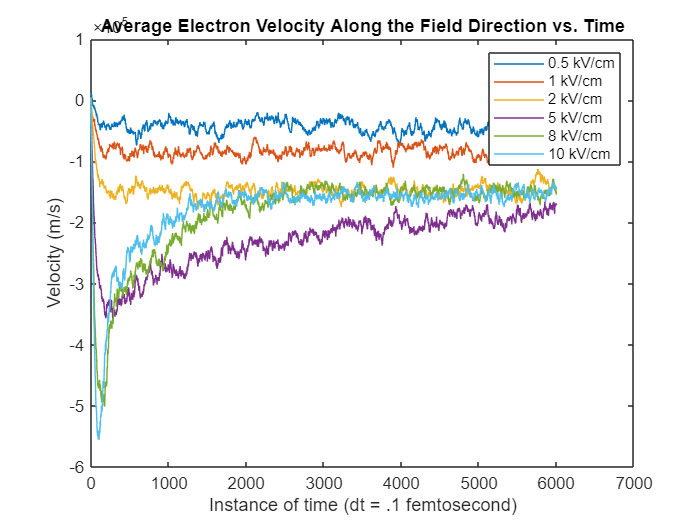

figure;
plot(v_z_ensemble);
title('Average Electron Velocity Along the Field Direction vs. Time');
ylabel('Velocity (m/s)');
xlabel('Instance of time (dt = .1 femtosecond)');
legend('0.5 kV/cm', '1 kV/cm', '2 kV/cm', '5 kV/cm', '8 kV/cm', '10 kV/cm');

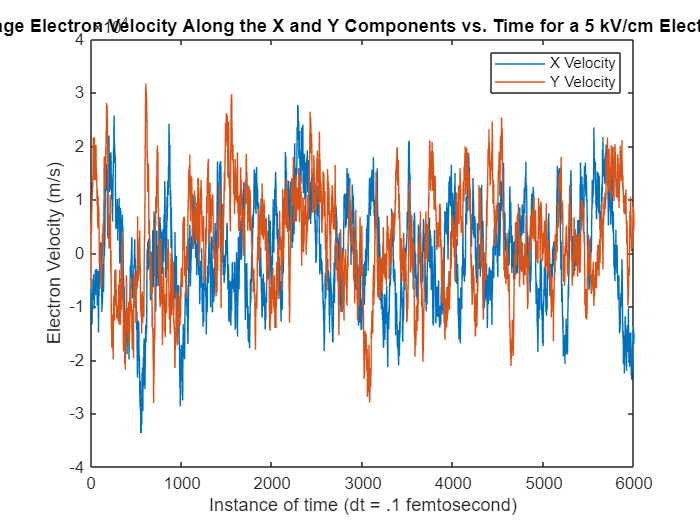

figure;
plot(v_x_ensemble);
hold on;
plot(v_y_ensemble);
title('Average Electron Velocity Along the X and Y Components vs. Time for a 5 kV/cm Electric Field');
ylabel('Electron Velocity (m/s)');
xlabel('Instance of time (dt = .1 femtosecond)');
legend('X Velocity', 'Y Velocity');

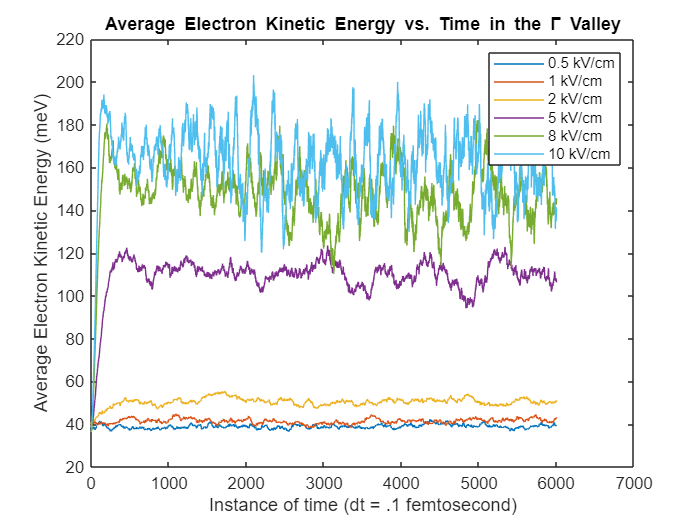

figure;
plot(E_ensemble_gamma / q * 1e3);
title('Average Electron Kinetic Energy vs. Time in the \Gamma Valley');
ylabel('Average Electron Kinetic Energy (meV)');
xlabel('Instance of time (dt = .1 femtosecond)');
legend('0.5 kV/cm', '1 kV/cm', '2 kV/cm', '5 kV/cm', '8 kV/cm', '10 kV/cm');

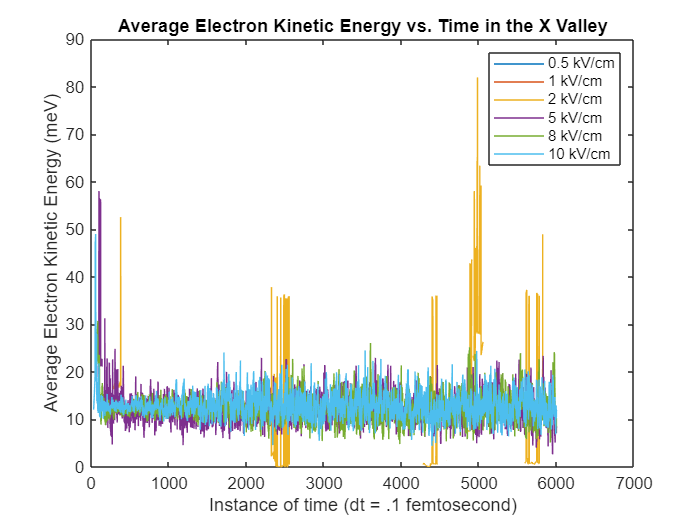

figure;
plot(E_ensemble_X / q * 1e3);
title('Average Electron Kinetic Energy vs. Time in the X Valley');
ylabel('Average Electron Kinetic Energy (meV)');
xlabel('Instance of time (dt = .1 femtosecond)');
legend('0.5 kV/cm', '1 kV/cm', '2 kV/cm', '5 kV/cm', '8 kV/cm', '10 kV/cm');

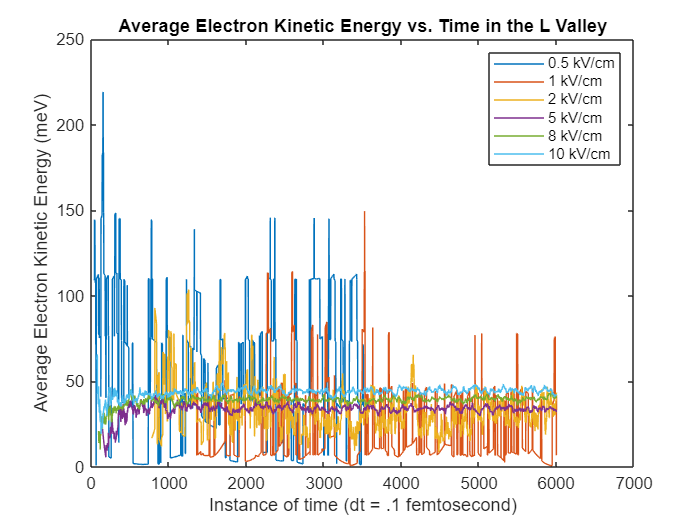

figure;
plot(E_ensemble_L / q * 1e3);
title('Average Electron Kinetic Energy vs. Time in the L Valley');
ylabel('Average Electron Kinetic Energy (meV)');
xlabel('Instance of time (dt = .1 femtosecond)');
legend('0.5 kV/cm', '1 kV/cm', '2 kV/cm', '5 kV/cm', '8 kV/cm', '10 kV/cm');

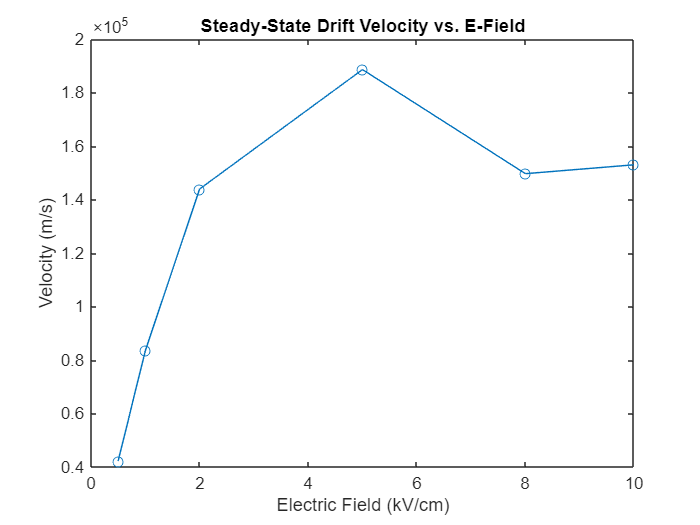

figure;
v_drift = mean(v_z_ensemble(end-999:end, :), 1);
plot(E * 1e-5, abs(v_drift), '-o');
title('Steady-State Drift Velocity vs. E-Field');
ylabel('Velocity (m/s)');
xlabel('Electric Field (kV/cm)');

mobility = 1e4 * abs(v_drift(2) - v_drift(1)) / (E(2) - E(1)); % cm^2 / Vs
fprintf('Low field electron mobiltiy in GaAs is %.2f cm^2 / Vs', mobility);

Low field electron mobiltiy in GaAs is 8250.80 cm^2 / Vs

fprintf(['This is very accurate compared to the experimentally measured mobiltiy of 8500 cm^2/Vs ...' ...
    'from https://www.ioffe.ru/SVA/NSM/Semicond/GaAs/electric.html#Hall']);

This is very accurate compared to the experimentally measured mobiltiy of 8500 cm^2/Vs ...from https://www.ioffe.ru/SVA/NSM/Semicond/GaAs/electric.html#Hall

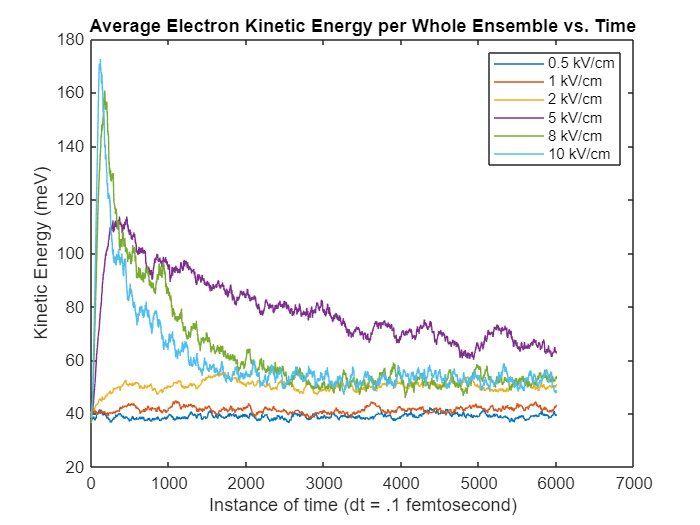

figure;
plot((E_ensemble / q) * 1e3);
title('Average Electron Kinetic Energy per Whole Ensemble vs. Time');
ylabel('Kinetic Energy (meV)');
xlabel('Instance of time (dt = .1 femtosecond)');
legend('0.5 kV/cm', '1 kV/cm', '2 kV/cm', '5 kV/cm', '8 kV/cm', '10 kV/cm');

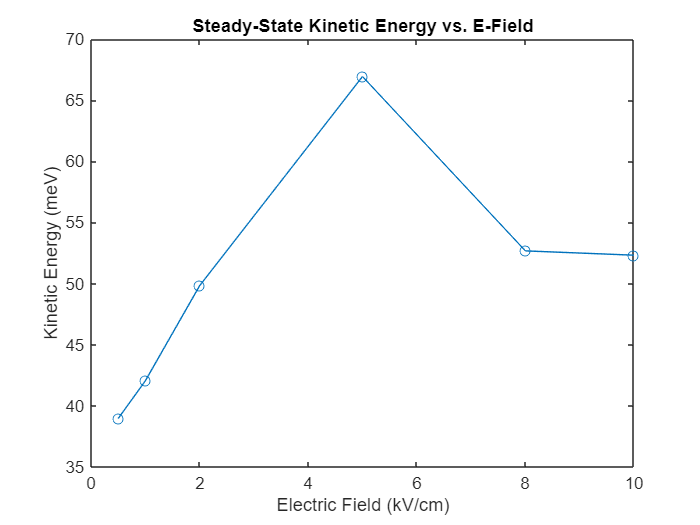

figure;
E_ss = mean(E_ensemble(end-999:end, :), 1);
plot(E * 1e-5, (abs(E_ss) / q) * 1e3, '-o');
title('Steady-State Kinetic Energy vs. E-Field');
ylabel('Kinetic Energy (meV)');
xlabel('Electric Field (kV/cm)');

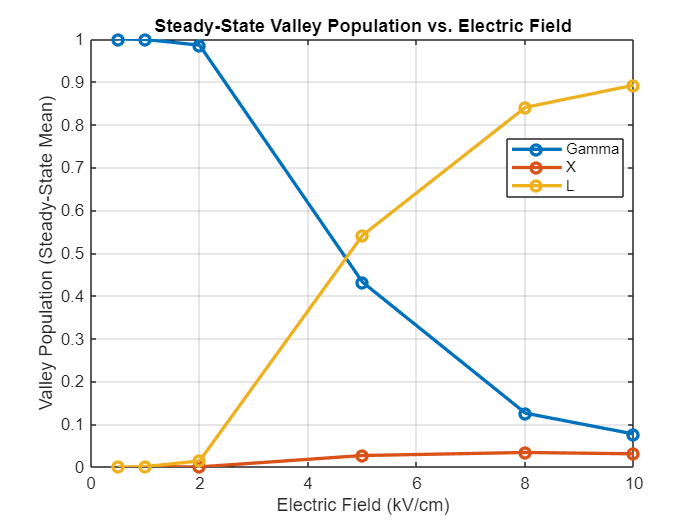

steady_state = mean(valley_ensemble(end-998:end, :), 1);
steady_state_reshaped = reshape(steady_state, 3, [])'; % [Gamma, X, L] per field

% Plotting
figure;
plot(E / 1e5, steady_state_reshaped, '-o', 'LineWidth', 2);
xlabel('Electric Field (kV/cm)');
ylabel('Valley Population (Steady-State Mean)');
legend('Gamma', 'X', 'L', 'Location', 'Best');
title('Steady-State Valley Population vs. Electric Field');
grid on;

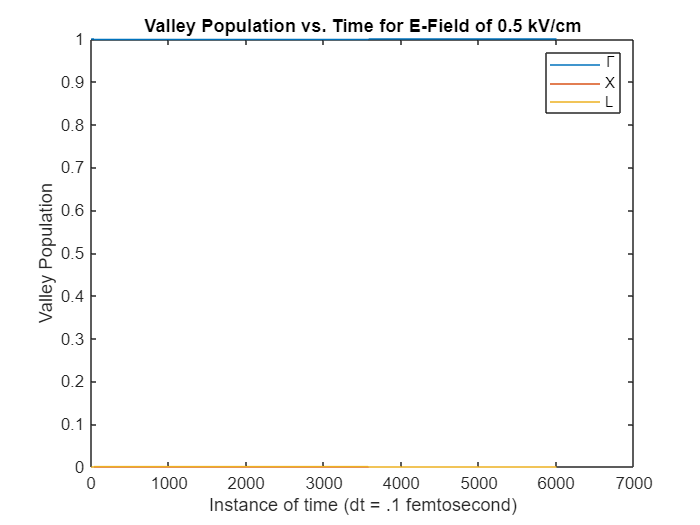

figure;
plot(valley_ensemble(:, 1:3));
title('Valley Population vs. Time for E-Field of 0.5 kV/cm');
ylabel('Valley Population');
xlabel('Instance of time (dt = .1 femtosecond)');
legend('\Gamma', 'X', 'L');

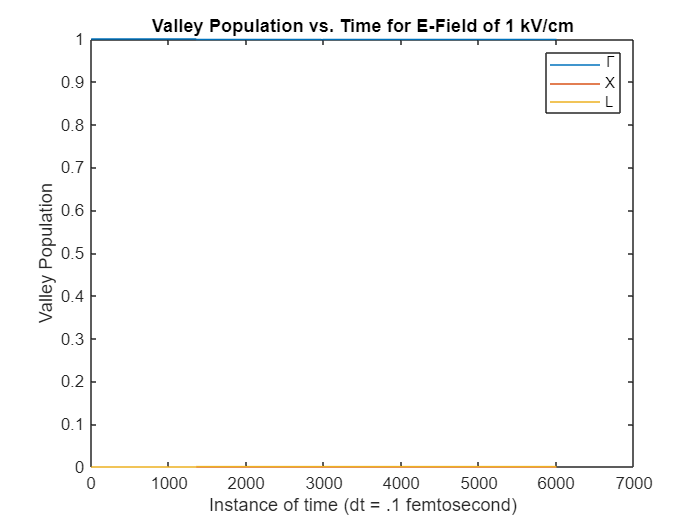

figure;
plot(valley_ensemble(:, 4:6));
title('Valley Population vs. Time for E-Field of 1 kV/cm');
ylabel('Valley Population');
xlabel('Instance of time (dt = .1 femtosecond)');
legend('\Gamma', 'X', 'L');

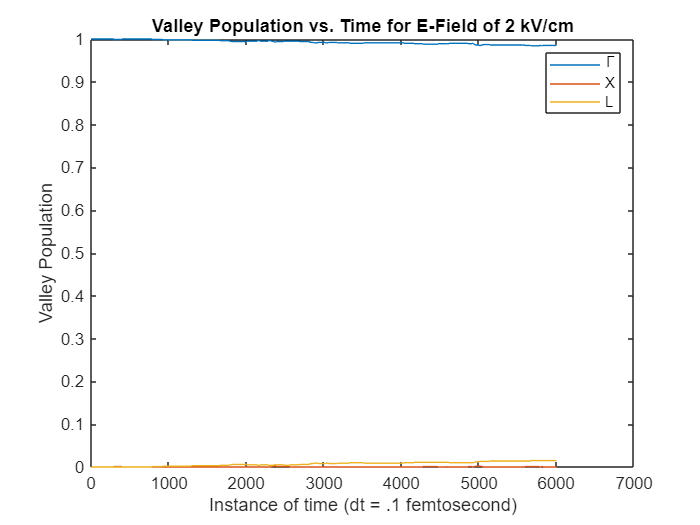

figure;
plot(valley_ensemble(:, 7:9));
title('Valley Population vs. Time for E-Field of 2 kV/cm');
ylabel('Valley Population');
xlabel('Instance of time (dt = .1 femtosecond)');
legend('\Gamma', 'X', 'L');

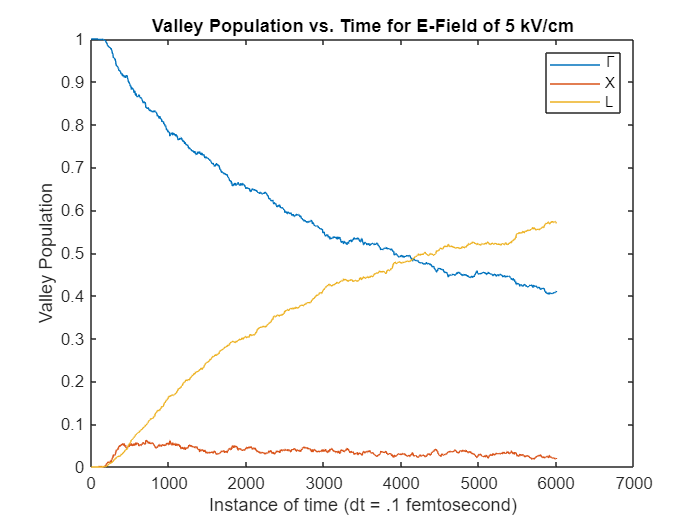

figure;
plot(valley_ensemble(:, 10:12));
title('Valley Population vs. Time for E-Field of 5 kV/cm');
ylabel('Valley Population');
xlabel('Instance of time (dt = .1 femtosecond)');
legend('\Gamma', 'X', 'L');

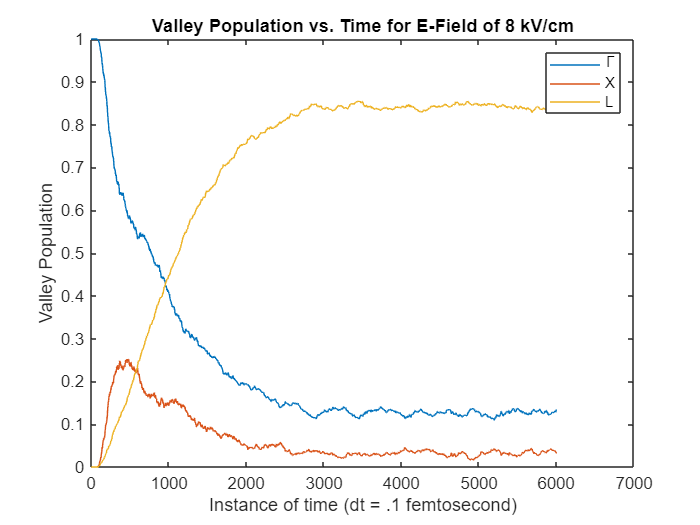

figure;
plot(valley_ensemble(:, 13:15));
title('Valley Population vs. Time for E-Field of 8 kV/cm');
ylabel('Valley Population');
xlabel('Instance of time (dt = .1 femtosecond)');
legend('\Gamma', 'X', 'L');

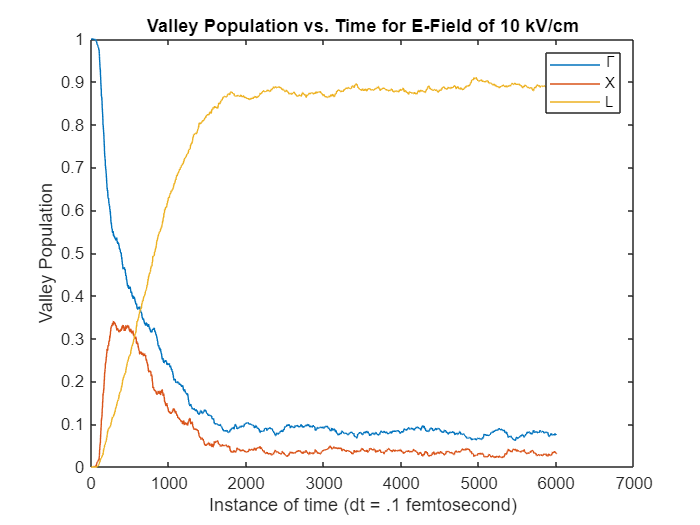

figure;
plot(valley_ensemble(:, 16:18));
title('Valley Population vs. Time for E-Field of 10 kV/cm');
ylabel('Valley Population');
xlabel('Instance of time (dt = .1 femtosecond)');
legend('\Gamma', 'X', 'L');

**Polar-Optical-Phonon Scattering**

function pop_scatter = pop_emit(E, m, h_bar, w_0, E_phonon, KB_J, q, e_inf, e_s, e_0, T)
    x = h_bar * w_0 / E;
    C = ((q^2 * w_0) / (8 * pi * e_0)) * sqrt(2 * m / (h_bar^2)) * ...
        ((1 / e_inf) - (1 / e_s)) * (1 / sqrt(E));
    N_0 = 1 / (exp(E_phonon / (KB_J * T)) - 1);
    
    if E > (h_bar * w_0)
        pop_scatter = C * ((N_0 + 1) * log(abs((1 + sqrt(1 - x)) / (1 - sqrt(1 - x)))));
    else
        pop_scatter = 0;
    end
end

function pop_scatter = pop_abs(E, m, h_bar, w_0, E_phonon, KB_J, q, e_inf, e_s, e_0, T)
    x = h_bar * w_0 / E;
    C = ((q^2 * w_0) / (8 * pi * e_0)) * sqrt(2 * m / (h_bar^2)) * ...
        ((1 / e_inf) - (1 / e_s)) * (1 / sqrt(E));
    N_0 = 1 / (exp(E_phonon / (KB_J * T)) - 1);
    
    pop_scatter = C * (N_0 * log(abs((1 + sqrt(1 + x)) / (-1 + sqrt(1 + x)))));
end

**Acoustic**

function acoustic = ac_scatter(E, m, h_bar, p, v_s, D, KB_J, T)
    acoustic = (D^2 * KB_J * T) / (2 * pi * h_bar * p * v_s^2) * ...
        ((2 * m) / (h_bar ^ 2)) ^ 1.5 * sqrt(E);
end

**Intervalley Scattering**

function gamma_inter_abs = inter_scatter_abs(E, h_bar, KB_J, T, D_if, Z_if, w_if, E_if, m_final, p, E_phonon)
    N_if = 1 / (exp(h_bar * w_if / (KB_J * T)) - 1);
    g_DOS = DOS(E + E_phonon - E_if, m_final, h_bar);
    gamma_inter_abs = N_if * (pi * D_if^2 * Z_if / (2 * p * w_if)) * g_DOS;
end

function gamma_inter_emit = inter_scatter_emit(E, h_bar, KB_J, T, D_if, Z_if, w_if, E_if, m_final, p, E_phonon)
    N_if = 1 / (exp(h_bar * w_if / (KB_J * T)) - 1);
    g_DOS = DOS(E - E_phonon - E_if, m_final, h_bar);
    gamma_inter_emit = (N_if + 1) * (pi * D_if^2 * Z_if / (2 * p * w_if)) * g_DOS;
end

**DOS**

function g_DOS = DOS(E, m, h_bar)
    if E > 0
        g_DOS = (sqrt(E) / (2 * (pi^2))) * (2 * m / (h_bar ^ 2)) ^ 1.5;
    else
        g_DOS = 0;
    end
end